# Customize Right Border of Entry That Spans Multiple Rows

To customize the right border of an entry that spans multiple rows:

- Specify the right border of the entry that spans the rows. This specification determines the border that is shared with the entry in the next column that is in the first row of the span.

- In the next column, specify the left border of the entries that are in the remaining rows of the span.

This example defines a table that has two rows and two columns. The entry in row one and column one spans two rows. To make the right border of this entry red along the entire span, the example specifies that:

- The right border of the row one, column one entry is red.

- The left border of the row two, column two entry is red.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myRowSpanBorder.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table that has two columns.

t = Table(2);
t.Style = [t.Style {VAlign("middleCentered")}];

Create the first row of the table.

tr1 = TableRow();

Create the first entry of the first row and specify that the entry spans two rows. Specify that the right border of the entry is red. Append the entry to the row.

te11 = TableEntry("entry 1,1");
te11.RowSpan = 2;
border = Border();
border.RightColor = 'red';
te11.Style = [te11.Style {border}];
append(tr1,te11);

Create the second entry of the first row and append the entry to the row. The left border of this entry is determined by the right border of the row one, column one entry.

te12 = TableEntry("entry 1,2");
append(tr1,te12);

Create the second entry of the second row, specify that the left border is red, and append the entry to the row.

tr2 = TableRow();
te22 = TableEntry("entry 2,2");
b = Border();
b.LeftColor = 'red';
te22.Style = [te22.Style {b}];
append(tr2,te22);

Append the rows to the table.

append(t,tr1);
append(t,tr2);

Add a title and the table to the slide.

replace(slide,"Title","Table Entry That Spans Multiple Rows");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

The right border of the first column entry is red along the entire span.

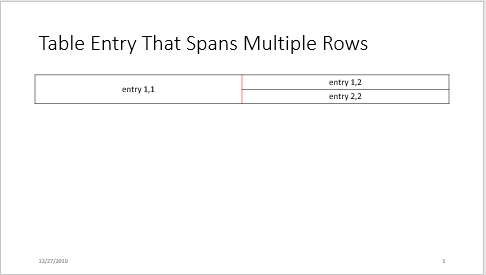

*Copyright 2019 The MathWorks, Inc.*